# **Deeplab Image Semantic Segmentation Algorithm**

**Network Generation, Training and Testing**

***S. Gardner, P. Fiorini, M. R. Haider***

**University of Alabama at Birmingham**

**Autonomous Vehicle Mobility Institution - Army Research Center**

**Updated: July 2022**

This algorithm inputs RELLIS images into DeeplabV3+ for semantic segmentation.

## Set flags

sanityCheck  = true;  % Check Deeplab performance
metricsCheck = true;  % Check Deeplab metrics
trainNew     = true; % Train the Deeplab algorithm

## Source the Datasets

Point to source location of **data**:

inputImagesTrain = ['C:\Users\stevendg\Desktop\UAB PhD\Projects\' ...
    '2020_6 AVML DoD Project\Lidar\data\Rellis_3D_pylon_camera_node\' ...
    'Rellis-3D\00003\pylon_camera_node'];
outputTeachTrain = ['C:\Users\stevendg\Desktop\UAB PhD\Projects\' ...
    '2020_6 AVML DoD Project\Lidar\data\Annotations\00003\' ...
    'pylon_camera_node_label_color'];

## Output Class Names

classes = ["grass"
           "tree"
           "pole"
           "sky"
           "vehicle"
           "log"
           "person"
           "bush"
           "concrete"
           "barrier"
           "puddle"
           "mud"
           "rubble"
           ];

#### Input/Teacher Datastores

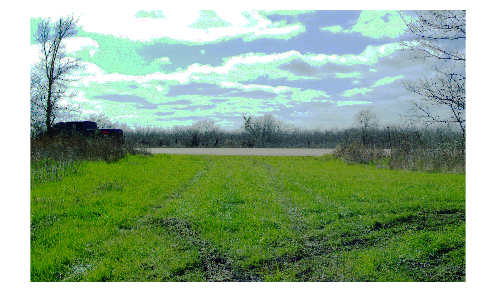

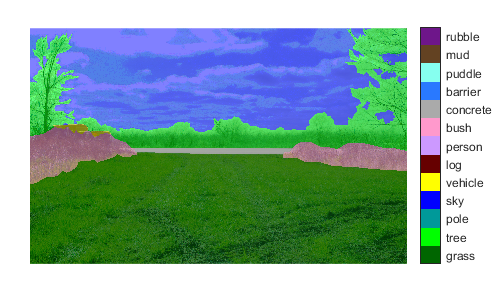

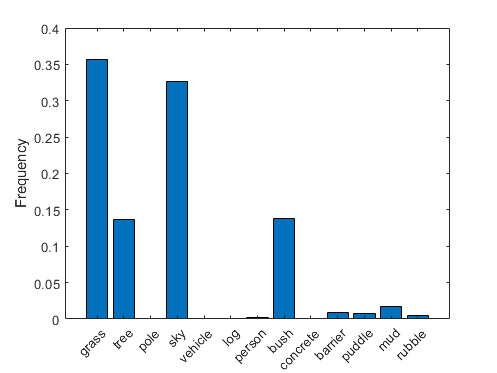

[imdsTrain,pxdsTrain,tblTrain] = generateDatastores(inputImagesTrain, ...
    outputTeachTrain,classes,sanityCheck,metricsCheck);

# Train/Import the Deeplab V3+ Network

#### Color Map

cmap = dataColorMap;

**Generate the Deeplab Network**

Takes several hours if training new net

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:11:11 |        4.91% |        6.98% |       2.9049 |       2.7811 |          0.0010 |
|       1 |           2 |       00:12:28 |        7.45% |              |       2.8776 |              |          0.0010 |
|       1 |           4 |       00:15:03 |       23.82% |              |       2.0673 |              |          0.0010 |
|       1 |           6 |       00:17:36 |       54.62% |              |       1.8860 |   

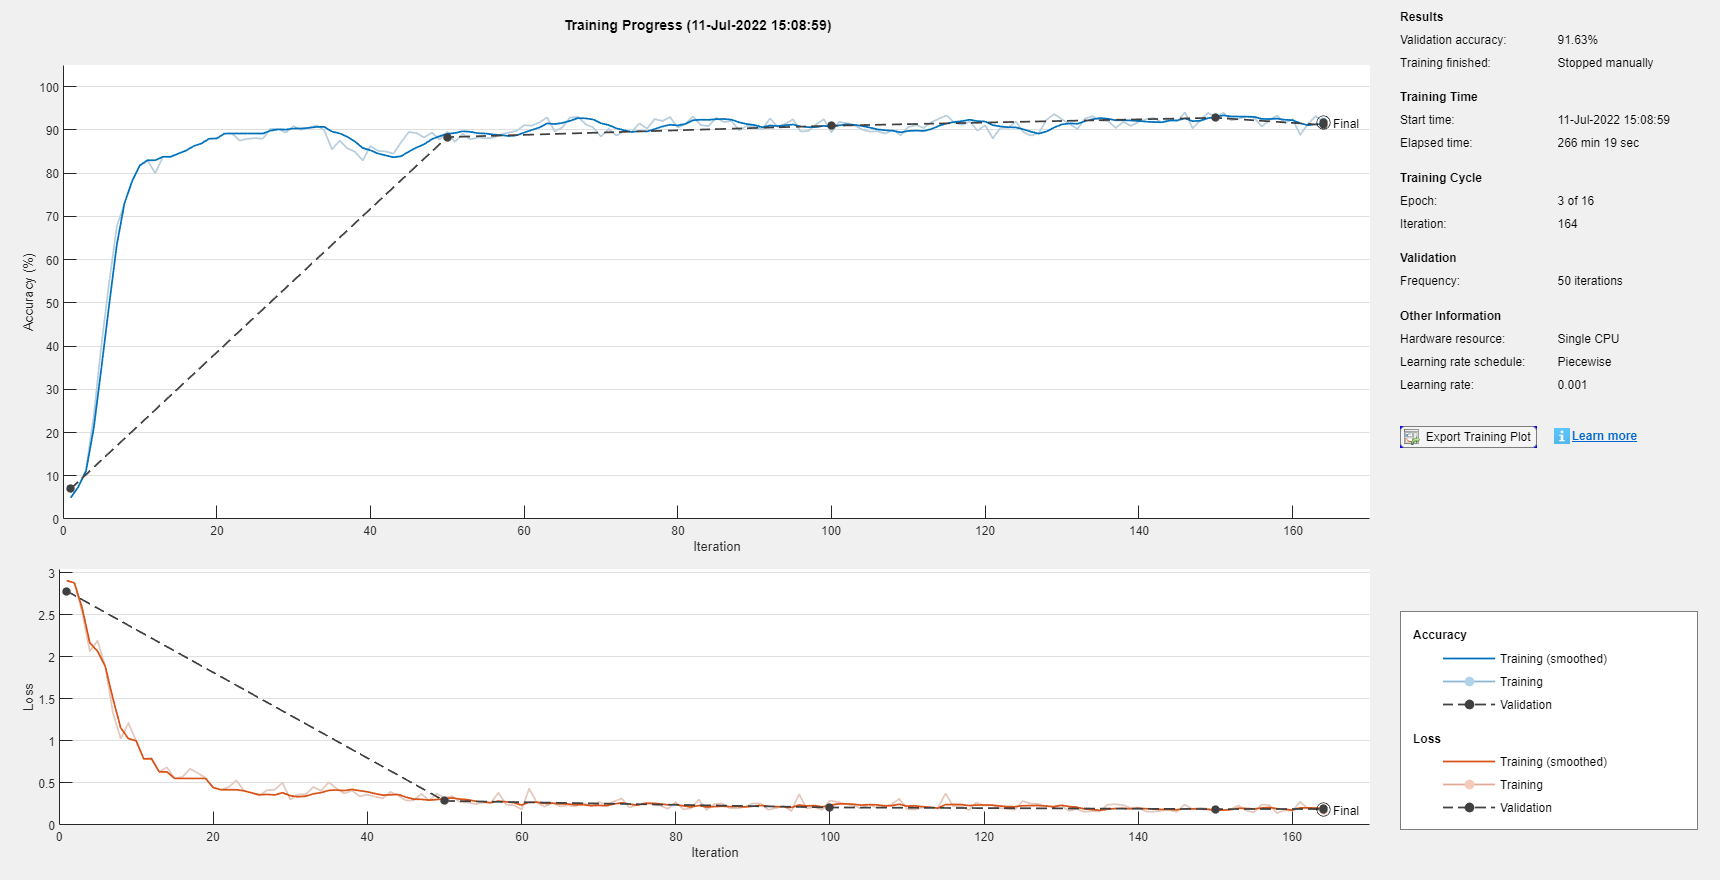

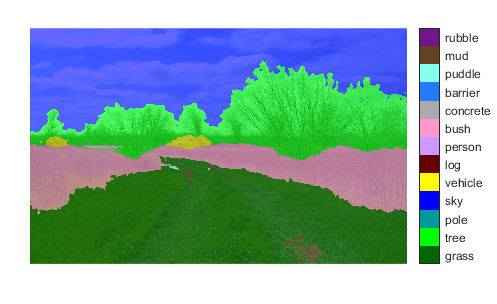

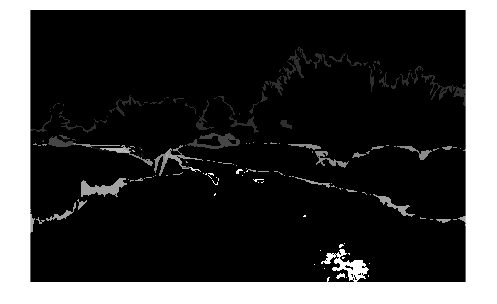

ans = 13×2 table
     classes        iou   
    __________    ________

    "grass"        0.94808
    "tree"         0.87439
    "pole"             NaN
    "sky"          0.95067
    "vehicle"      0.26903
    "log"              NaN
    "person"           NaN
    "bush"         0.87283
    "concrete"     0.27854
    "barrier"          NaN
    "puddle"        0.2449
    "mud"         0.086068
    "rubble"           NaN


ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.91126          0.94005       0.5906       0.86016          NaN    


ans = 13×3 table
                Accuracy      IoU       MeanBFScore
                ________    ________    ___________

    grass       0.82909      0.81877      0.57777  
    tree        0.94785      0.87171      0.89921  
    pole        0.98785     0.036914          NaN  
    sky         0.97629      0.97341      0.95148  
    vehicle     0.98213      0.28447          NaN  
    log         0.94474      0.57048          NaN  
    person      0.98999      0.64312          NaN  
    bush        0.93029      0.80914       0.7225  
    concrete    0.99207      0.45438          NaN  
    barrier     0.97994      0.82194          NaN  
    puddle       0.8539       0.4849          NaN  
    mud  

net = generateDLN(imdsTrain,pxdsTrain,classes,tblTrain,cmap, ...
    trainNew,sanityCheck,metricsCheck);


if trainNew
    save('dlnet.mat','net','cmap','classes');
end